%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain length on DNA/DNA TMSD
%kinetics 

g = 2 %define invader toehold length 

g = 2


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp %* exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward or reverse transitions rates 
    Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]

    
    Pn_j0 = zeros(1,numel(Kf))
    Pn_j0 (1) = 0
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_j0(Pn)  = 1/Kf(Pn) + Kb(Pn-1)/Kf(Pn)*Pn_j0(Pn-1)
    end

    first_pass_time (b-9) = sum(Pn_j0) %calculate first passage time
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8)) %calculate effective rate constant
    prob_unbound(b-9) = Pn_j0(end)/sum(Pn_j0) %calculate probability of being in unbound state
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-7 *

         0    0.1852         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0100         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0100    0.0008         0


Pn_j0 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.7402


first_pass_time = 	1.0e+04 *

    1.7402         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.1493         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-7 *

         0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0111         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0111    0.0009         0


Pn_j0 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.9335


first_pass_time = 	1.0e+04 *

    1.7402    1.9335         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.1493    1.0344         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-7 *

         0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0122         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0122    0.0010         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1268


first_pass_time =     1.7402    1.9335    2.1268         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0133         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0133    0.0011         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.3201


first_pass_time =     1.7402    1.9335    2.1268    2.3201         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0144         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0144    0.0012         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.5134


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0155         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0155    0.0012         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.7066


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0166         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0166    0.0013         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.8999


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0177         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0177    0.0014         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.0932


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0188         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0188    0.0015         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.2865


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0200         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0200    0.0016         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.4798


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0211         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0211    0.0017         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.6731


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.8663


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0233         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0233    0.0019         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.0596


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0244         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0244    0.0020         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.2529


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0255         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0255    0.0021         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.4462


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0266         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0266    0.0021         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.6395


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0277         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0277    0.0022         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.8328


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0288         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0288    0.0023         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0261


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0299         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0299    0.0024


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0299    0.0024


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0310


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0310


Pn_j0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0310


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126         0         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059         0         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992         0         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925         0         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858         0         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791         0         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723         0         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723    6.7656         0         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043    0.2956         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723    6.7656    6.9589         0         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043    0.2956    0.2874         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723    6.7656    6.9589    7.1522         0


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043    0.2956    0.2874    0.2796         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723    6.7656    6.9589    7.1522    7.3455


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043    0.2956    0.2874    0.2796    0.2723


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_CD = 54000000

k_DC = 0

k_DD = 1

Kf =     0.0000    5.4000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.1852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0002    0.3031    0.6061    0.9091         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271         0         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574         0         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877         0         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180         0


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


Pn_j0 =          0    0.0000    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5151    0.5453    0.5756    0.6059    0.6362    0.6665    0.6968    0.7271    0.7574    0.7877    0.8180    0.8483


first_pass_time =     1.7402    1.9335    2.1268    2.3201    2.5134    2.7066    2.8999    3.0932    3.2865    3.4798    3.6731    3.8663    4.0596    4.2529    4.4462    4.6395    4.8328    5.0261    5.2193    5.4126    5.6059    5.7992    5.9925    6.1858    6.3791    6.5723    6.7656    6.9589    7.1522    7.3455


k_eff =     1.1493    1.0344    0.9404    0.8620    0.7957    0.7389    0.6897    0.6466    0.6086    0.5747    0.5445    0.5173    0.4927    0.4703    0.4498    0.4311    0.4138    0.3979    0.3832    0.3695    0.3568    0.3449    0.3338    0.3233    0.3135    0.3043    0.2956    0.2874    0.2796    0.2723


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


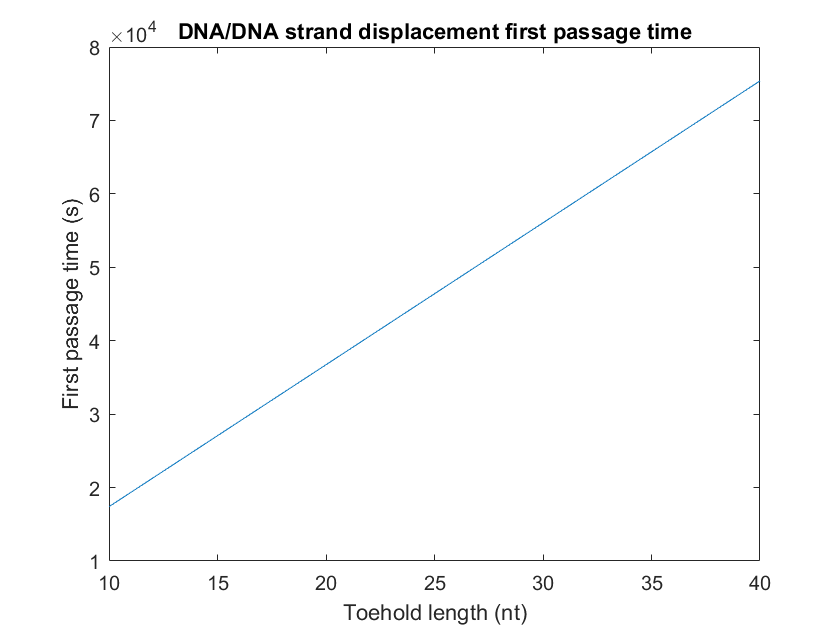

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

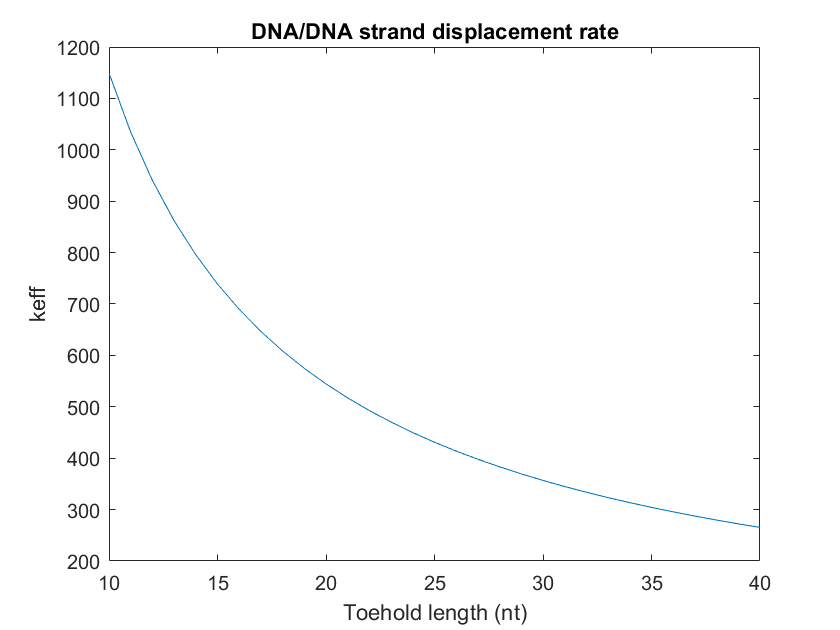


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

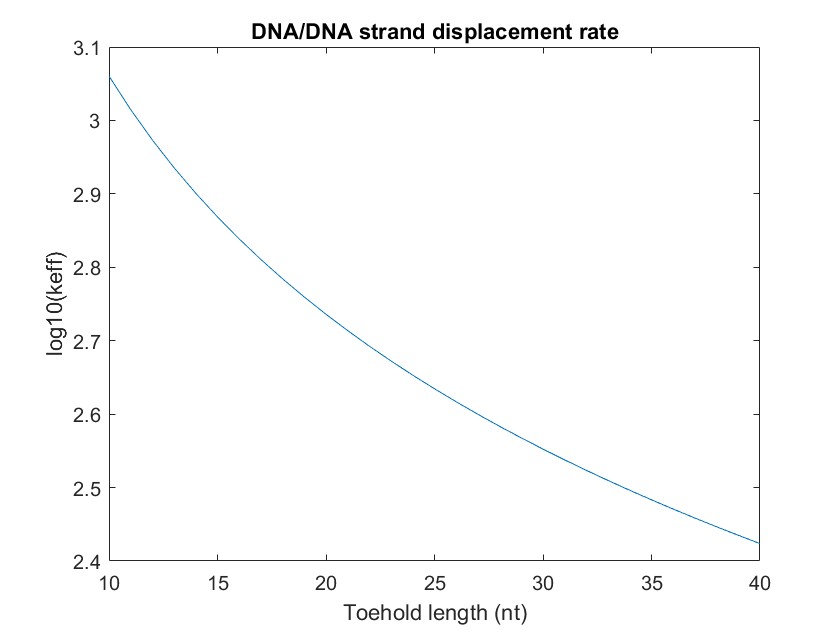


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  